# 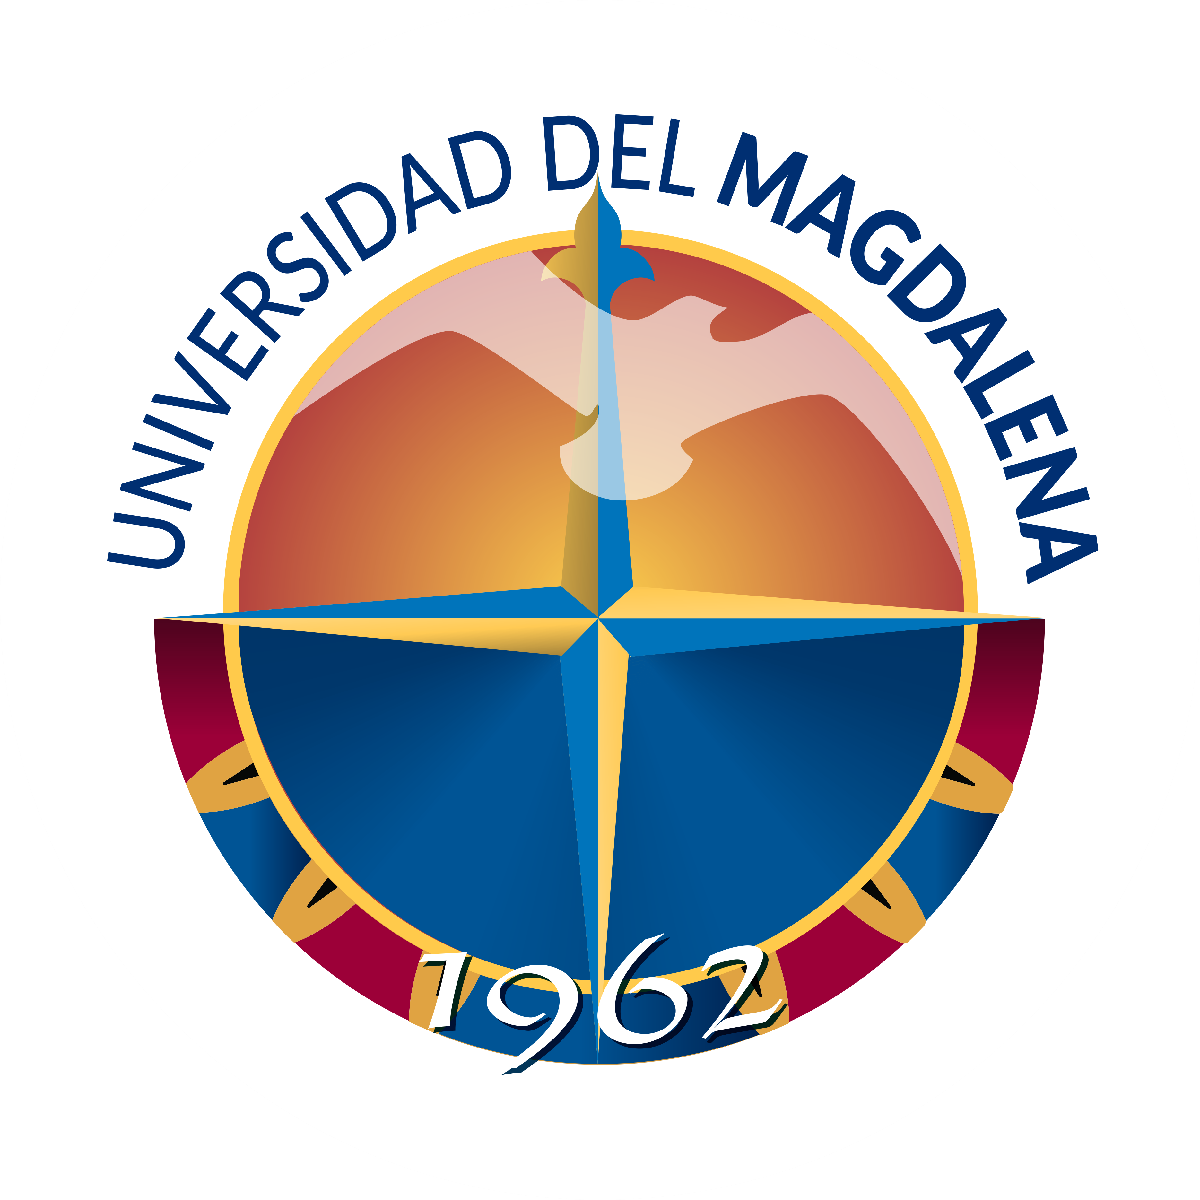

## Programa de Ingeniería Electrónica

#### Procesamiento de contenido multimedia

Periodo lectivo 2022 - II

#### Práctica desarrollada Por:

Martin Ceballos, 2019119086

Jose Quintana, 2018119049

# **LABORATORIO No. 1**

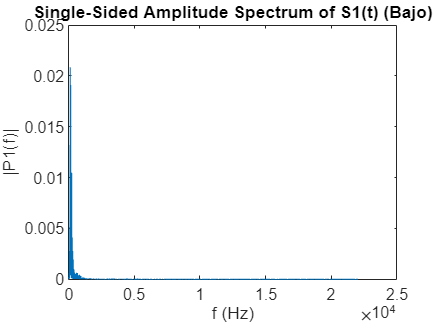

%% Importar Señales de Audio
clear all; close all; clc;

% Importación de audios a utilizar 
gm = importdata("Bajo 5 seg.mp3");
sm = importdata("Trompeta 5 seg.mp3");

%Ajuste de tamaño de los vectores de los audios para poder sumarlos
sm = sm.data;
sm = sm(:,1);
sm = sm(1:190000);

gm = gm.data;
gm = gm(:,1);
gm = gm(1:190000);

%Mezcla de las dos señales
ym = sm + gm;

% Frecuencia de muestreo teniendo en cuenta el Teorema de Nyquist-Shannon
fs = 44100;                    
T = 1/fs;             % Sampling period       
L = length(ym);       % Length of signal
t = (0:L-1)*T;        % Time vector

%Reproducción de señal combinada
sound(ym,fs)
pause(5)

% Espectro de la señal 1 (Bajo)
Y = fft(gm);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = fs*(0:(L/2))/L;

plot(f,P1) 
title('Single-Sided Amplitude Spectrum of S1(t) (Bajo)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

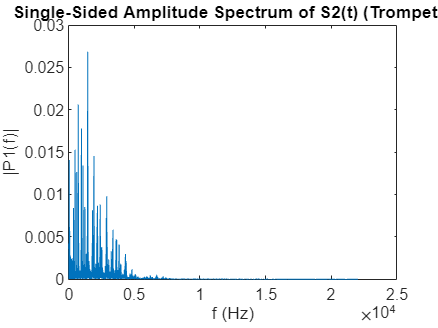


% Espectro de la señal 2 (Trompeta)
Y = fft(sm);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);   
P1(2:end-1) = 2*P1(2:end-1);

f = fs*(0:(L/2))/L;

plot(f,P1) 
title('Single-Sided Amplitude Spectrum of S2(t) (Trompeta)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

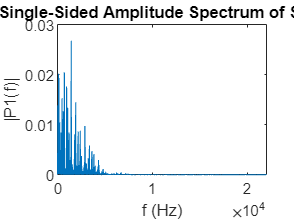


% Espectro de la señal 3 (Señal combinada)
Y = fft(ym);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = fs*(0:(L/2))/L;

plot(f,P1) 
title('Single-Sided Amplitude Spectrum of S3(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

## FILTRO PasaAlto

% Filtrando la señal del Bajo

Fstop = 500;     % Stopband Frequency
Fpass = 1000;    % Passband Frequency|
Astop = 80;      % Stopband Attenuation (dB)
Apass = 1;       % Passband Ripple (dB)
match = 'both';  % Band to match exactly

% Construct an FDESIGN object and call its ELLIP method.
h  = fdesign.highpass(Fstop, Fpass, Astop, Apass, fs);
Hd = design(h, 'ellip', 'MatchExactly', match);

ymf1 = filter(Hd,ym);
sound(ymf1,fs)

## FILTRO PasaBajo

% Filtrando la señal de la Trompeta

N     = 15;    % Order
Fpass = 450;  % Passband Frequency
Apass = 1;     % Passband Ripple (dB)
Astop = 80;    % Stopband Attenuation (dB)

% Construct an FDESIGN object and call its ELLIP method.
h  = fdesign.lowpass('N,Fp,Ap,Ast', N, Fpass, Apass, Astop, fs);
Hd = design(h, 'ellip');

ymf1 = filter(Hd,ym);
sound(ymf1,fs)